clear;
close all;
clc;

%% 参数设置
n_adc_samples = 256; % number of ADC samples per chirp
chirpLoop = 1;
n_rx=1;
Fs=0.218e6;

% Fs=5e6;             %ADC采样率 
c=3*1e8;            %光速
t_ramp=124*(n_adc_samples+55)/27e6;
% ts=n_adc_samples/Fs;%ADC采样时间
Periodicity=47e-3; %帧周期??
% B_valid =ts*slope;  %有效带宽
% B =3997.56e9;  %有效带宽
B=5000e6; %5000MHz
k=B/t_ramp;    %调频斜率 
fs=1/Periodicity;

fname = ['G:\CODE\FYP_matlab\120GHz0318\47ms\data15', '.bin'];
% fname = ['C:\Users\asd\Desktop\120GHz0318\data4', '.bin'];

    %读取处理后的.bin二进制文件，并以16进制整型写入到RawData矩阵。
fid = fopen(fname, 'r');
RawData = fread(fid, 'int16');
fclose(fid);

fileSize = size(RawData, 1);
%计算chirps数：数据量/天线数/采样点数/2(实部和虚部各占一个数据)。
n_chirps= fileSize/2/n_adc_samples;
%读取所有ComplexData数据并写入数组ComplexData，总维数为：数据量/2(实部和虚部各占一个数据)。
ComplexData = zeros(1, fileSize/2);
IQ_matrix = reshape(RawData,[256,n_chirps*2]);
IQ_matrix=IQ_matrix';%每行256 I一行，Q一行
I_matrix=IQ_matrix(1:2:end,:);
Q_matrix=IQ_matrix(2:2:end,:);
I_chirps=reshape(I_matrix',[1,n_chirps*256]);
Q_chirps=reshape(Q_matrix',[1,n_chirps*256]);
for i=1:1:fileSize/2
    ComplexData(1, i) = I_chirps(i) + 1i*Q_chirps(i);
end
%将数组ComplexData转换成矩阵Chirp_Division，每行数据为1个chirp的数据(含4个天线)，行高为总chirp数。
Chirp_Division = reshape(ComplexData, n_adc_samples*n_rx, n_chirps);
%转置。
Chirp_Division = Chirp_Division.';

%定义Rx_Division为“Rx行，n_chirps*n_adc_samples列”的矩阵,其每行数据为每根天线接受的总数据。
Rx_Division = zeros(n_rx, n_chirps*n_adc_samples);
for row = 1:n_rx
    for i = 1: n_chirps
        Rx_Division(row, (i-1)*n_adc_samples+1:i*n_adc_samples) = Chirp_Division(i, (row-1)*n_adc_samples+1:row*n_adc_samples);
    end
end
    
%将Rx_Division数据按“采样点数，天线，chirp*frame”重排列成Sample_Division，按采样点分离数据。
Sample_Division = reshape(Rx_Division, n_adc_samples, n_rx, n_chirps);
%取第1根天线的采样数据。
Rx_1 = zeros(n_adc_samples, n_chirps);
Rx_1(:) = Sample_Division(:, 1, :);
%时间平均背景减法。
Data1filtOut = zeros(size(Rx_1));
Background = mean(Rx_1, 2);     %返回矩阵每行的平均值。                	
for i=1:n_chirps                                             
    %data1每个值都减去所在行的平均值(background)。
    Data1filtOut(:, i) = Rx_1(:, i) - Background;    
end

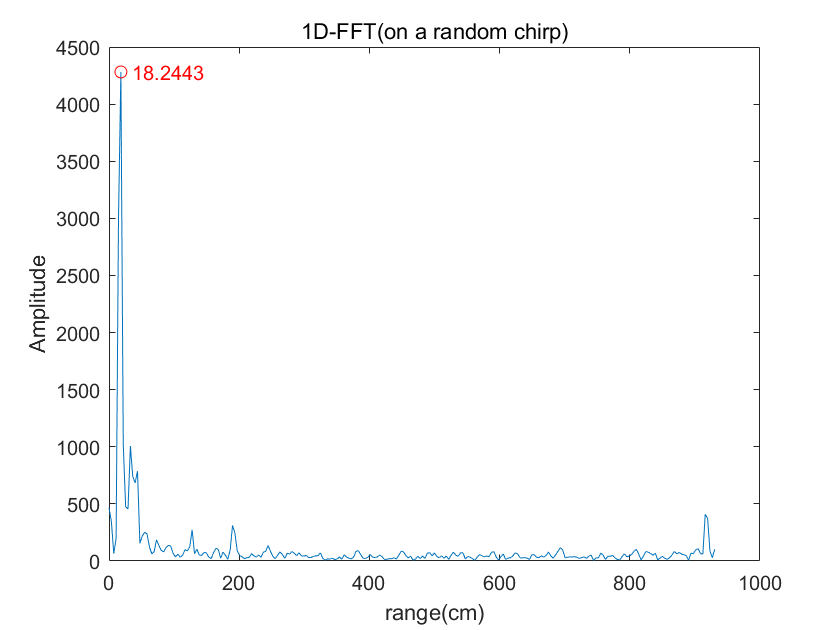

% n=chirpLoop/2:chirpLoop:length(Data1filtOut);
IF_mat=Data1filtOut;
[N,M]=size(IF_mat); %N为每chirp采样点，M为chirp数

%% 生成窗
range_win = hamming(N);  %生成range窗

%% range fft
for i = 1:1:M
    temp = IF_mat(:,i) .* range_win;
    temp_fft = fft(temp,N);
    IF_mat(:,i) = temp_fft;
%     IF_mat(:,i)=temp_fft-mean(temp_fft); %平均相消法滤除杂波
end

%找range-bin
% range_bin=(0:N-1)*c*Fs/N/2/k*100; %转换为cm
range_bin=(0:N-1)*c*Fs/N/2/k*100; %转换为cm
time=linspace(0,M*Periodicity,M);
[Val,Locs]=max(abs(IF_mat));
[Locs,ord]=mode(Locs); %众数，频次
% range_bin(Locs)

% 某chirp的1D-fft图
for i = 1:1:M
    [a,b]=max(abs(IF_mat(:,i)));
    if b==Locs
       example_chirp=b;
       example_Val=a;
       break
    end
end
figure;
plot(range_bin, abs(IF_mat(:,i))); %abs
text(range_bin(example_chirp),example_Val,['  ',num2str(range_bin(example_chirp))],'Color','red'); %]
hold on
plot(range_bin(example_chirp),example_Val,'ro');
title('1D-FFT(on a random chirp)');
ylabel('Amplitude'); 
xlabel('range(cm)');

%慢时间采样：Locs代表每个chirp取第Locs个采样点的数据。
% n=chirpLoop/2:chirpLoop:length(Data1filtOut);
Data_tmp=Data1filtOut;
Data_tmp = reshape(Data_tmp(Locs, :), [], 1);
% Data_tmp=Data_tmp(1:1024);
data_num=length(Data_tmp);

% %IQ不平衡补偿
% %求均值
% I_before_correction = real(Data_tmp)-mean(real(Data_tmp));
% Q_before_correction = imag(Data_tmp)-mean(imag(Data_tmp));
% 
% %估计参数
% e = sqrt(mean(Q_before_correction.*Q_before_correction)/mean(I_before_correction.*I_before_correction))-1;
% phi = -asin(mean(I_before_correction.*Q_before_correction)/sqrt(mean(I_before_correction.*I_before_correction)*mean(Q_before_correction.*Q_before_correction)));
% %P矩阵求解
% P = [1,0;tan(phi),1/((1+e)*cos(phi))];
% 
% %计算IQ
% for i=1:length(I_before_correction)
% IQ(:,i) = P*[I_before_correction(i);Q_before_correction(i)];
% end
% %重组信号
% I =IQ(1,:);
% Q =IQ(2,:);
% signal_IQ = I+Q*1j;
% figure();
% pwelch(signal_IQ,  [],[],[],fs);title('Spectrum at Rx baseband after I/Q correction');

% 不考虑IQ不平衡
I =real(Data_tmp);
Q =imag(Data_tmp);
signal_IQ = I+Q*1j;
% %图形绘制
% t=linspace(0,length(I)/fs,length(I));
% plot(t,I)
% % ylim([-2,2])
% title('不平衡补偿后的I');
% plot(t,Q)
% % ylim([-2,2])
% title('不平衡补偿后的Q');

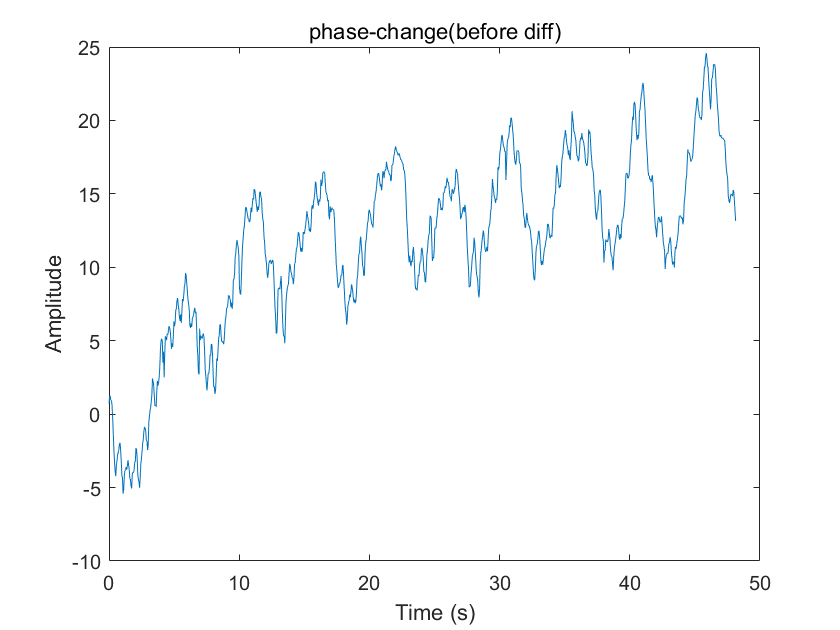

%相位提取和解缠绕
angle_data=angle(signal_IQ);
angle_data=unwrap(angle_data);
%线性去趋势
% angle_data = detrend(angle_data);
% %转置
% angle_data=angle_data'; 
% angle_data=(angle_data-mean(angle_data));
t=linspace(0,data_num*Periodicity,data_num);
figure;
plot(t, angle_data);
xlabel('Time (s)'); 
ylabel('Amplitude'); 
title('phase-change(before diff)');

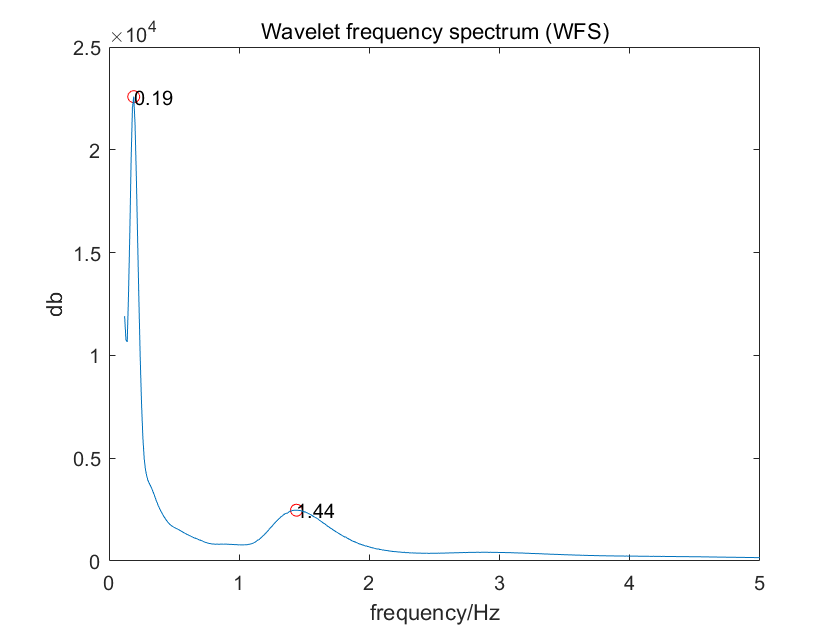

%CWT小波变换
x = angle_data;

wavename='cmor1-1.4'; %复morlet小波函数
%频率转尺度
fmin=0.12;
fmax=5;
df=0.01;
f=fmin:df:fmax;%预期的频率
wcf=centfrq(wavename); %小波的中心频率
scal=fs*wcf./f;%利用频率转换尺度 系数a
% scal=[1:0.1:2];%系数a
t=linspace(0,length(x)/fs,length(x));
coefs = cwt(x,scal,wavename);  %,'plot'显示系数图
figure;
% plot(f,sum(abs(coefs),2));
[Val,Locs]=findpeaks(sum(abs(coefs),2),'minpeakheight',2400,'NPEAKS',3);
for i = 1:1:length(Locs)
    plot(f(Locs(i)),Val(i),'ro');
    text(f(Locs(i)),Val(i),num2str(f(Locs(i))))
    hold on
end
semilogy(f,sum(abs(coefs),2));
xlabel('frequency/Hz');
ylabel('db');
% xlim([0,0.5])
% ylim([0,200])
title('Wavelet frequency spectrum (WFS)');